## Gallery function

Plots a series of images in a single figure window. It should be better than montage in the following ways:

- Display images of different resolutions

- Default to keeping the montage shape to that of the screen

- Change root directory of the images using relative paths

- Sort images by an variable

Inputs should be the same as those accepted by montage i.e.

- Table with a filename column that could be specified

- String or cell string array

- Array of image data

In addition what might be nice is to display:

- A directory of images

## Display a list of full image paths:

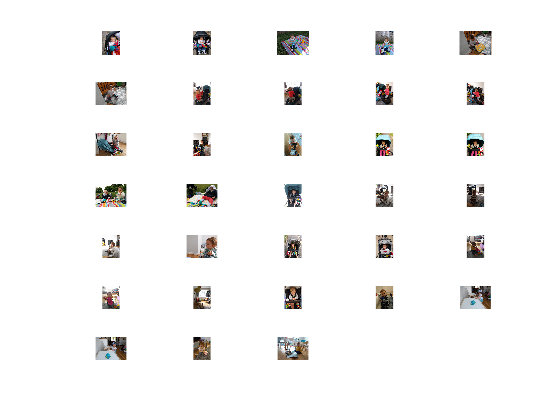

root = 'C:\Data\family_photos\tagged';
files = dir(fullfile(root, '*.jpg'));
filenames = {files.name};
filenames = cellfun(@(x) fullfile(root, x), filenames', 'UniformOutput', false);
Gallery(filenames);